clc;
clear all
%% ---------- Paths & load ----------
outdir = 'D:\Jazmin\MultichannelDataTanks\HIP\RvsP';

Spk = load('D:\Jazmin\MultichannelDataTanks\HIP\RvsP\spikes_win_extract_mean.mat'); 
Spk_P = load('D:\Jazmin\MultichannelDataTanks\HIP\RvsP\spikes_win_extract_meanP.mat'); 

DEV_P = Spk_P.spikesP.DEVP_win_bins;
STD_P = Spk_P.spikesP.STDP_win_bins;

DEV = Spk.spikes.DEV_win_bins;
STD = Spk.spikes.STD_win_bins;

CTR = Spk.spikes.CTR_win_bins;

DEV_sig = Spk.spikes.DEV_at37;  
DEV_P_sig = Spk_P.spikesP.DEVP_at37;

%% ================================================================
%  FULL WORKING SCRIPT (with significance asterisks)
%  - Builds 4-in-1 bar plot with means ± SEM:
%      Group1: DEV vs DEV_P (red)
%      Group2: STD vs STD_P (blue)
%      Group3: CTR only (green)
%      Group4: DEV_sig vs DEV_P_sig (dark red)
%  - Paired t-tests for ALL pairwise comparisons (Cohen's d, CIs)
%  - Holm–Bonferroni correction (robust to NaNs)
%  - Adds asterisks above bars for the 3 key pairs using Holm-adjusted p
%  - One-way ANOVA (anova1) across conditions
%  - Saves Excel with stats and the figure as PNG

%% --- 0) Safety checks ---------------------------------------------------
reqVars = {'DEV_P','STD_P','DEV','STD','CTR','DEV_sig','DEV_P_sig'};
for v = 1:numel(reqVars)
    if ~exist(reqVars{v},'var')
        error('Missing variable "%s" in workspace.', reqVars{v});
    end
    sz = size(eval(reqVars{v}));
    if numel(sz)~=2 || sz(2)~=16
        warning('%s is %s, expected ~20x16. Proceeding but check your data.', ...
            reqVars{v}, mat2str(sz));
    end
end

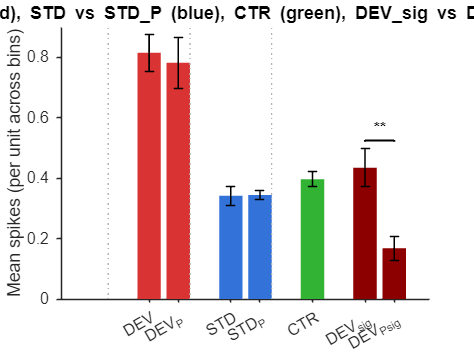


%% --- 1) Collapse to per-unit means (20x1 each) -------------------------
m = @(X) mean(X, 2, 'omitnan');
DEV_u       = m(DEV);
DEV_P_u     = m(DEV_P);
STD_u       = m(STD);
STD_P_u     = m(STD_P);
CTR_u       = m(CTR);
DEV_sig_u   = m(DEV_sig);
DEV_P_sig_u = m(DEV_P_sig);

rawNames = {'DEV','DEV_P','STD','STD_P','CTR','DEV_sig','DEV_P_sig'}; % 1x7
dataCols = [DEV_u, DEV_P_u, STD_u, STD_P_u, CTR_u, DEV_sig_u, DEV_P_sig_u]; % 20x7

%% --- 2) Pairwise paired t-tests (all pairs) ----------------------------
nConds = size(dataCols,2);
nPairs = nConds*(nConds-1)/2;
pairA = cell(nPairs,1);
pairB = cell(nPairs,1);
pvals = nan(nPairs,1);
tvals = nan(nPairs,1);
dfs   = nan(nPairs,1);
ci_low  = nan(nPairs,1);
ci_high = nan(nPairs,1);
d_cohen = nan(nPairs,1);

row = 0;
for i = 1:nConds-1
    for j = i+1:nConds
        row = row + 1;
        a = dataCols(:,i);
        b = dataCols(:,j);
        [~,p,ci,stats] = ttest(a, b);                    % paired t-test
        diffAB = a - b;
        d = mean(diffAB, 'omitnan') / std(diffAB, 0, 'omitnan'); % Cohen's d (paired)

        pairA{row}   = rawNames{i};
        pairB{row}   = rawNames{j};
        pvals(row)   = p;
        tvals(row)   = stats.tstat;
        dfs(row)     = stats.df;
        ci_low(row)  = ci(1);
        ci_high(row) = ci(2);
        d_cohen(row) = d;
    end
end

PairwiseRaw = table(pairA, pairB, tvals, dfs, pvals, ci_low, ci_high, d_cohen, ...
    'VariableNames', {'Cond_A','Cond_B','t','df','p','CI_low','CI_high','Cohens_d'});

%% --- 3) Holm–Bonferroni (robust to NaNs) -------------------------------
p_use = pvals(:);                 % column
nan_mask = isnan(p_use);
p_use(nan_mask) = 1;              % treat NaNs as non-sig for sorting

[psorted, idxSort] = sort(p_use, 'ascend');   % columns
mHB = numel(psorted);
alpha = 0.05;

% Column thresholds; elementwise comparison
holm_thresh = alpha ./ (mHB - ((1:mHB)') + 1);    % m x 1

% Step-down decisions
rej_sorted = psorted <= holm_thresh;
first_false = find(~rej_sorted, 1, 'first');
if ~isempty(first_false)
    rej_sorted(first_false:end) = false;      % monotonic
end

% Map decisions back to original order
rej = false(size(p_use));
rej(idxSort) = rej_sorted;

% Holm adjusted p-values (monotone non-decreasing)
padj_sorted = zeros(mHB,1);
for k = 1:mHB
    padj_sorted(k) = min( max( (mHB - (1:k)' + 1) .* psorted(1:k) ), 1);
end
for k = 2:mHB
    padj_sorted(k) = max(padj_sorted(k), padj_sorted(k-1));
end

padj = nan(size(pvals));           % keep NaNs where original p was NaN
padj(idxSort) = padj_sorted;

PairwiseHolm = PairwiseRaw;
PairwiseHolm.HolmAdjP     = padj;
PairwiseHolm.Reject_Holm  = rej;

%% --- 4) Plot: 4 sets of bars in one figure -----------------------------
means = mean(dataCols, 1, 'omitnan');
sems  = std(dataCols, 0, 1, 'omitnan') ./ sqrt(size(dataCols,1));

% Colors
c_red     = [0.85 0.2 0.2];
c_blue    = [0.2 0.45 0.85];
c_green   = [0.2 0.7 0.2];
c_darkred = [0.55 0.0 0.0];
colors = [c_red; c_red; c_blue; c_blue; c_green; c_darkred; c_darkred];

% Grouping: [DEV, DEV_P] | [STD, STD_P] | [CTR] | [DEV_sig, DEV_P_sig]
groupSizes = [2, 2, 1, 2];
barLabels  = {'DEV','DEV_P','STD','STD_P','CTR','DEV_{sig}','DEV_P_{sig}'};

% X positions with gaps between groups
gap = 0.8;
x = []; startX = 1;
for g = 1:numel(groupSizes)
    k = groupSizes(g);
    x = [x, startX:(startX+k-1)]; %#ok<AGROW>
    startX = startX + k + gap;
end

figure('Color','w'); hold on;
for i = 1:numel(means)
    bar(x(i), means(i), 0.8, 'FaceColor', colors(i,:), 'EdgeColor','none');
end
for i = 1:numel(means)
    errorbar(x(i), means(i), sems(i), 'k', 'LineStyle','none', 'LineWidth',1);
end
xticks(x);
xticklabels(barLabels);
ylabel('Mean spikes (per unit across bins)');
title('DEV vs DEV\_P (red), STD vs STD\_P (blue), CTR (green), DEV\_{sig} vs DEV\_P\_{sig} (dark red)');
box off; set(gca,'TickDir','out');

% Group separators (light dotted lines)
yl = ylim; startSep = 1;
for g = 2:numel(groupSizes)
    sep = startSep - gap/2 - 1;
    plot([sep sep], yl, ':', 'Color', [0.7 0.7 0.7]);
    startSep = startSep + groupSizes(g-1) + gap;
end
ylim(yl);

%% --- 5) Add asterisks for significant paired comparisons ---------------
% Uses Holm-adjusted p-values from PairwiseHolm for the 3 key pairs.
pairsToMark = {
    'DEV','DEV_P';
    'STD','STD_P';
    'DEV_sig','DEV_P_sig';
};

% helper to convert p to asterisks (* <.05, ** <.01, *** <.001)
p2stars = @(p) repmat('*', 1, sum(p < [0.05 0.01 0.001]));

% We’ll place a horizontal cap between the two bars and put the stars above it
yl = ylim; yr = diff(yl);
capHeight = 0.03;         % distance above the taller bar (as fraction of y-range)
textHeight = 0.01;        % extra lift for the text (fraction of y-range)
tick = 0.005;             % small vertical ticks at ends

for k = 1:size(pairsToMark,1)
    % indices of conditions in the bar order
    idxA = find(strcmp(rawNames, pairsToMark{k,1}));
    idxB = find(strcmp(rawNames, pairsToMark{k,2}));
    if isempty(idxA) || isempty(idxB), continue; end

    % find the corresponding row in PairwiseHolm (A,B are in ascending condition order there)
    mask = strcmp(PairwiseHolm.Cond_A, pairsToMark{k,1}) & strcmp(PairwiseHolm.Cond_B, pairsToMark{k,2});
    r = find(mask, 1);
    if isempty(r), continue; end

    p_corr = PairwiseHolm.HolmAdjP(r);
    if isnan(p_corr) || p_corr >= 0.05, continue; end

    % y position just above the taller bar (considering error bars)
    yA = means(idxA) + sems(idxA);
    yB = means(idxB) + sems(idxB);
    yTop = max(yA, yB);
    yLine = yTop + capHeight*yr;
    yText = yLine + textHeight*yr;

    % make sure y-limits accommodate the annotation
    yl = ylim; yr = diff(yl);
    needTop = yText + 0.02*yr;
    if needTop > yl(2)
        ylim([yl(1), needTop]);
        yl = ylim; yr = diff(yl);
        % recompute line/text with possibly changed yr
        yLine = yTop + capHeight*yr;
        yText = yLine + textHeight*yr;
    end

    % draw cap and ticks
    plot([x(idxA) x(idxA) x(idxB) x(idxB)], ...
         [yLine-tick*yr yLine yLine yLine-tick*yr], ...
         'k','LineWidth',1.2);
    % draw stars
    text(mean([x(idxA) x(idxB)]), yText, p2stars(p_corr), ...
        'HorizontalAlignment','center', 'VerticalAlignment','bottom', 'FontWeight','bold');
end

% Save figure
figName = ['barsets_' datestr(now,'yyyymmdd_HHMMSS') '.png'];
try
    exportgraphics(gcf, figName, 'Resolution', 300);
catch
    saveas(gcf, figName);
end


%% --- 6) One-way ANOVA across conditions (anova1) -----------------------
Y = dataCols(:);
G = repelem(rawNames, size(dataCols,1))';
[p_anova, tbl_anova, stats_anova] = anova1(Y, G, 'off'); %#ok<ASGLU>

% Convert ANOVA table
anovaTbl = cell2table(tbl_anova(2:end,:), 'VariableNames', tbl_anova(1,:));

%% --- 7) Descriptives ----------------------------------------------------
desc = table( ...
    rawNames', ...
    mean(dataCols, 1, 'omitnan')', ...
    (std(dataCols,0,1,'omitnan') ./ sqrt(size(dataCols,1)))', ...
    std(dataCols,0,1,'omitnan')', ...
    'VariableNames', {'Condition','Mean','SEM','SD'});

%% --- 8) Save outputs ----------------------------------------------------
xlsName = ['spike_stats_' datestr(now,'yyyymmdd_HHMMSS') '.xlsx'];
writetable(desc,           xlsName, 'Sheet','descriptives');
writetable(PairwiseRaw,    xlsName, 'Sheet','pairwise_ttests_raw');
writetable(PairwiseHolm,   xlsName, 'Sheet','pairwise_ttests_Holm');
writetable(anovaTbl,       xlsName, 'Sheet','anova1');

fprintf('Figure saved: %s\n', figName);

Figure saved: barsets_20250928_122037.png


fprintf('Stats Excel:  %s\n', xlsName);

Stats Excel:  spike_stats_20250928_122039.xlsx


fprintf('ANOVA p = %.4g\n', p_anova);

ANOVA p = 8.246e-18



%% --- 9) Emphasize key paired comparisons (console) ---------------------
keyPairs = {
    'DEV','DEV_P';
    'STD','STD_P';
    'DEV_sig','DEV_P_sig';
};
for k = 1:size(keyPairs,1)
    mask = strcmp(PairwiseHolm.Cond_A, keyPairs{k,1}) & strcmp(PairwiseHolm.Cond_B, keyPairs{k,2});
    r = find(mask,1);
    if ~isempty(r)
        fprintf('%s vs %s -> t(%d)=%.3f, p=%.4g, Holm adj=%.4g, reject=%d, d=%.3f\n', ...
            PairwiseHolm.Cond_A{r}, PairwiseHolm.Cond_B{r}, PairwiseHolm.df(r), ...
            PairwiseHolm.t(r), PairwiseHolm.p(r), PairwiseHolm.HolmAdjP(r), ...
            PairwiseHolm.Reject_Holm(r), PairwiseHolm.Cohens_d(r));
    end
end

DEV vs DEV_P -> t(19)=0.695, p=0.4952, Holm adj=1, reject=0, d=0.155
STD vs STD_P -> t(19)=-0.103, p=0.9187, Holm adj=1, reject=0, d=-0.023
DEV_sig vs DEV_P_sig -> t(19)=4.539, p=0.0002242, Holm adj=0.002466, reject=1, d=1.015


DEVmed_sig = mean(DEV_sig,2);
DEVmed_sig_P = mean(DEV_P_sig,2);

DEVmed = mean(DEV,2);
DEVmed_P = mean(DEV_P,2);

CTRmed = mean(CTR,2);

CTRmed =    0.453212733809123
   0.400827575736832
   0.410541405327898
   0.395672912692811
   0.349040822584887
   0.364439832944685
   0.514412183729970
   0.458383689536152
   0.500719108557149
   0.495300593568303



STDmed = mean(STD,2);
STDmed_P = mean(STD_P,2);

% Assemble into a table
T = table(DEVmed_sig, DEVmed_sig_P, DEVmed, DEVmed_P, CTRmed, STDmed, STDmed_P, ...
    'VariableNames', {'DEVmed_sig','DEVmed_sig_P','DEVmed','DEVmed_P','CTRmed','STDmed','STDmed_P'});

% Write to Excel
outFile = 'hippocampal_means.xlsx';
writetable(T, outFile, 'Sheet', 'Means', 'WriteVariableNames', true);

fprintf('Saved %d rows to %s (sheet: Means).\n', height(T), outFile);

Saved 20 rows to hippocampal_means.xlsx (sheet: Means).
